## Loading Data section

clearvars inImageStack tiff_info tiff_stack tiff_pix_size tiff_stack_1d
%inImageStack = []; inImageStack = '20190924_1407_dt-t.tif';
inImageStack = []; inImageStack = uigetfile('*.tif');

tiff_info = []; tiff_info = imfinfo(inImageStack); % return tiff structure, one element per image
tiff_stack = []; tiff_stack = double(imread(inImageStack, 1)); % read in first image
tiff_pix_size = []; tiff_pix_size = tiff_info.Width; % Read Pixel Size;
%concatenate each successive tiff to tiff_stack
for ii = 2 : size(tiff_info, 1)
    temp_tiff = double(imread(inImageStack, ii));
    tiff_stack = cat(3 , tiff_stack, temp_tiff);
end
clear('ii', 'temp_tiff')
% tiff_stack = tiff_stack *1000;
% tiff_stack_min = min(min(min(tiff_stack)));
%tiff_stack = tiff_stack - tiff_stack_min;

%Save a copy on disk
if exist('tiff_stack.tiff', 'file')==2
    delete('tiff_stack.tiff');
end
pause(1)
saveastiff(single(tiff_stack),...
    'tiff_stack.tiff')

The file was saved successfully. Elapsed time : 0.452 s.


ans = 0

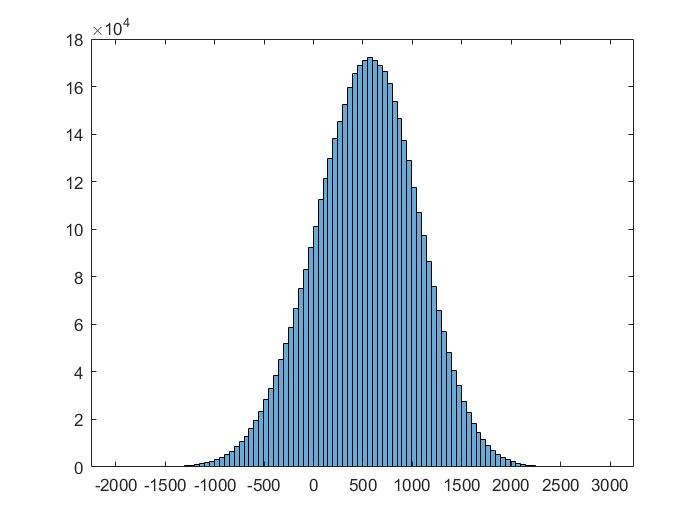

clearvars ans tiff_pix_size
%Preview the image stack in Matlab
ViewImageStack(tiff_stack)
tiff_stack_1D = reshape(tiff_stack, [], 1);
histogram(tiff_stack_1D, 100)

clearvars tiff_stack_1D

## Make guess for the intial values

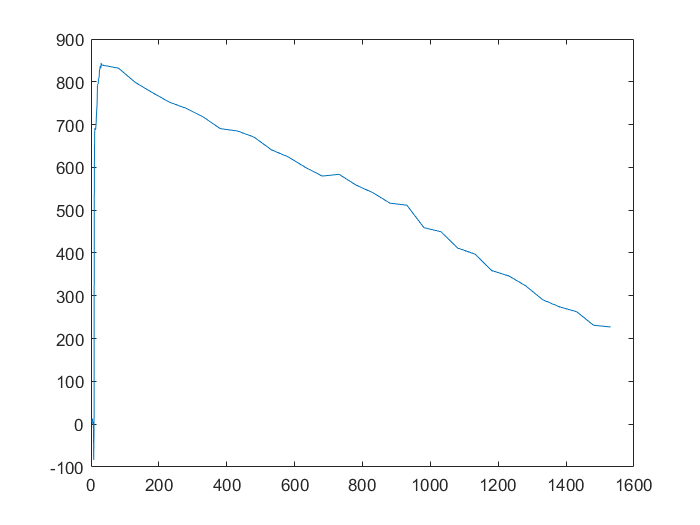

clearvars tData yData estT0 estTau estAmp estBas
tData = csvread('time_delay.txt'); % Input tData
yData = reshape (mean(tiff_stack, [1 2]), [size(tData, 1) 1]);

% Estimate the initial guesses
estT0 = min(tData(tData<40 & yData>0.3 * max(yData)));
estTau = max(tData(tData>tData(yData==max(yData)) & tData<max(tData(yData>(max(yData)/3)))));
estAmp = max(yData) - min(yData);
estBas = min(yData(1:5, 1));
estOff = yData(end);

plot(tData, yData)

## Selecting the Fitting Model

Now go the specific script to generate the function of your choice with designered parameters being initialized. Once the function is setup and function file is created **come back here** and simulate the function with the transient of the average of FOV.  

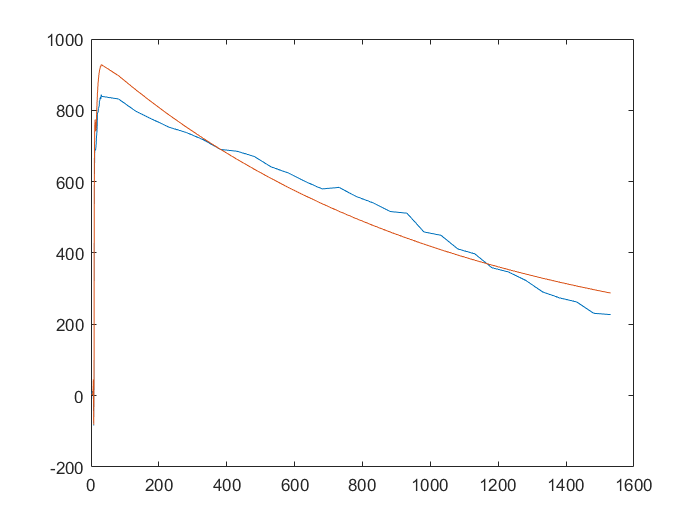

% 2 Exponential Rise and Decay + Tail Offest + XPM (Coherent Artifact)  
% The model is analytically convoluted with the IRF
%
% This file generates the custom function for being 
% used in the fitting process. Assign 1 or 0 if a 
% parameter is global or fixed. After running this 
% this script the "<function name>_Mod.m" will be
% re-written with the updated parameter setup.
%
% For fixed parameters, the value should be set 
% here.
%
% clear % Comment this if you don't want to clean the workspace during the 
        % model selection and testing process
% Clear all the used variable to make sure they are empty for consistency
clearvars x0 xLow xHigh 
clearvars j i ans
clearvars fileID par_val par_names par_set par_set_size par_cont use_fit_res
clearvars ax1 ax2 tx1 tx2 sx1 sx2 a1 t1 a2 t2 t_rd a_off t_off base t0 FWHM 
clearvars func_script

use_fit_res = 1; % 1: Replace the initial guess with the fitted results
                 % 0: Use the values in the script

% Define the parameters with this order
% par = [value fix_boolean Global_Boolean Low_Bound High_Bound]
% -- XPM parameters
ax1 = [1572 1 0 0 10000];
ax2 = [0.44 1 0 0 10000];
tx1 = [-0.66 1 0 -10 10];
tx2 = [2.7 1 0 0 10];
sx1 = [2 1 0 0.1 10];
sx2 = [8.5 1 0 0.1 10];
% -----------------
% -- Rise Decay
a1 = [850 0 0 0 10000];
t1 = [1000 0 0 0.6 10000];
a2 = [0 1 0 0 50000];
t2 = [700 1 0 0.6 10000];
t_rd = [5.2 0 0 0 100];
% -----------------
% -- Offset
a_off = [100 0 0 0 1000];
t_off = [1E5 1 0 1E4 1E6];
% ----------------
% -- Other Parameters
base = [3 0 0 -100 100];
t0 = [7.9 1 0 6 15];
FWHM = [0.52 1 0 0.1 1];

par_names = ["ax1 = ", "ax2 = ", "tx1 = ", "tx2 = ",...
    "sx1 = ", "sx2 = ", "a1 = ", "t1 = ",...
    "a2 = ", "t2 = ", "t_rd = ", "a_off = ", "t_off = ", "base = ",...
    "t0 = ", "FWHM = "];
par_names = par_names';
par_set = [ax1; ax2; tx1; tx2; sx1; sx2; a1; t1; a2; t2; t_rd; a_off; t_off; base; t0; FWHM];
par_set_size = size(par_set, 1);

% If use_fit_res is 1, the fitted result will be replaced in the par_set
% first column (initial values).
if exist('par_cont', 'var') == 1 && use_fit_res == 1
   par_set(:, 1) = str2double(par_cont(:, 5)); 
end

par_val = ""; % This will contain the lines for parameter setup in 
              % in the modified function file
j=0;
for i = 1:par_set_size
    if par_set(i, 2) == 0
       j = j+1;
       par_val(i,1) = "x("+j+" , 1);";
    else
       par_val(i,1) = string(par_set(i, 1))+";"; 
    end
end
clearvars j i

par_cont = [par_names'; par_val']; % Parameter List (String)

% The modified function for the model is defined here
func_script = [...
    "k1 = 1/t1;";...
    "k2 = 1/t2;";...
    "k_rd = 1/t_rd;";...
    "k_off = 1/t_off;";...
    "ts = tData - t0;";...
    "sigma = FWHM/2.35483;";...
    "";...
    "x_neg = -1/(sqrt(2 * pi)) * exp(-(ts + tx1).^2/(2 * (sx1 * sigma)^2));";...
    "x_pos = +1/(sqrt(2 * pi)) * exp(-(ts - tx2).^2/(2 * (sx2 * sigma)^2));";...
    "exp_rd = 0.5 * exp(1/2 * k_rd * (-2 * ts + k_rd * sigma^2));";...
    "err_rd = erfc((k_rd * sigma^2 - ts)/(sigma * sqrt(2)));";...
    "exp1 = 0.5*exp(1/2 * k1 * (-2 * ts + k1 * sigma^2));";...
    "err1 = erfc((k1 * sigma^2 - ts)/(sigma * sqrt(2)));";...
    "exp2 = 0.5*exp(1/2 * k2 * (-2 * ts + k2 * sigma^2));";...
    "err2 = erfc((k2 * sigma^2 - ts)/(sigma * sqrt(2)));";...
    "exp_off = 0.5*exp(1/2 * k_off * (-2 * ts + k_off * sigma^2));";...
    "err_off = erfc((k_off * sigma^2 - ts)/(sigma * sqrt(2)));";...
    "";...
    "comp_x = ax1 * (x_neg + ax2 * x_pos);";...
    "comp1 = -a1 * k_rd / (k1 - k_rd) * abs((exp_rd .* err_rd - exp1 .* err1));";...
    "comp2 = -a2 * k_rd / (k2 - k_rd) * abs((exp_rd .* err_rd - exp2 .* err2));";...
    "comp_off = a_off * (exp_off .* err_off);";...
    "";...
    "out=base + comp_x + comp1 + comp2 + comp_off;";...
    "";...
    "end";...
    ];

% Write all the data to the "<function name>.m" file
fileID = fopen('fit2ExpRDAnOffX_Mod.m', 'w+');
fprintf(fileID, 'function out = fit2ExpRDAnOffX_Mod(x, tData)\n');
fprintf(fileID, '\n');
fprintf(fileID, '%8s %s\n', par_cont);
fprintf(fileID, '\n');
fprintf(fileID, '%s\n', func_script);
fclose(fileID);
pause(1);

par_cont = [par_cont; par_set(:, 2)'; par_set(:,1)'];
par_cont = par_cont'; 

% Setup the initial guess "x0" and the upper and lower bounds 
j=0;
for i = 1:par_set_size
    if par_set(i, 2) == 0
       j = j+1;
       x0(j, 1) = par_set(i, 1);
       xLow(j, 1) = par_set(i, 4);
       xHigh(j, 1) = par_set(i, 5);
    end
end
clearvars j i  ans 

% Clean up the workspace
clearvars fileID par_val par_names use_fit_res 
clearvars ax1 ax2 tx1 tx2 sx1 sx2 a1 t1 a2 t2 t_rd  a_off t_off base t0 FWHM 
clearvars func_script

% Test the model 
% Comment if you don't want this 
plot(tData, yData, tData, fit2ExpRDAnOffX_Mod(x0, tData))

## Check the model and the intial guess for the average of FOV

clearvars decModel;
% decModel = @(x, tData)fit2expAn_Mod(x, tData)
decModel = @(x, tData)fit2ExpRDAnOffX_Mod(x, tData)

decModel = function_handle with value:
    @(x,tData)fit2ExpRDAnOffX_Mod(x,tData)


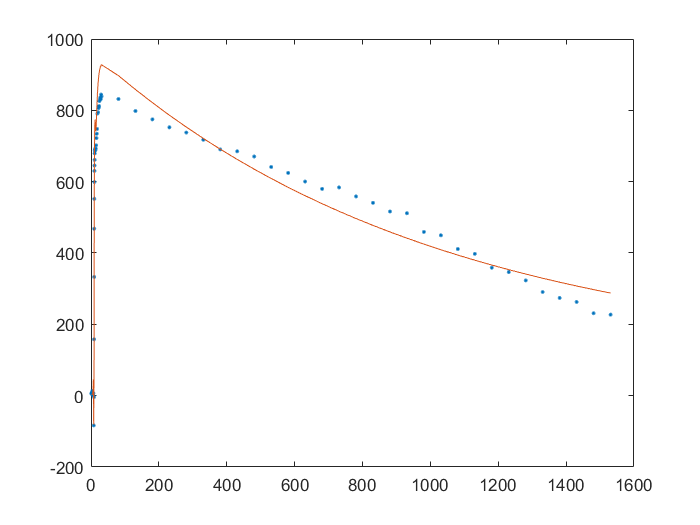


plot(tData , yData, '.', tData, decModel(x0, tData))

## Fitting the average of FOV to the model to find a good starting point for pixel-by-pixel fitting process

% generate costumized starting points for multistart
clearvars ptsGen pts tpoints rpts allpts
ptsGen = @(a) 10*a .*rand(10,1) + a - 5*a;
pts = ptsGen(x0');
tpoints = CustomStartPointSet(pts);
rpts = RandomStartPointSet('NumStartPoints',4);
allpts = {tpoints,rpts};
clearvars ptsGen pts tpoints rpts

clearvars minProblem opts problem ms x tElapsed yDataSim xFit xFitEst ...
    fovAve fovAveSim
% Define a optimization problem if using "fmincon"
% minProblem = @(x)sum((decModel(x, tData)-yData(:,1)).^2);

tic; % Zero the timer
% rng default % For reproducibility
% opts = optimoptions(@fmincon,...
%     'FunctionTolerance', 1e-5,...
%     'StepTolerance', 1e-7,...
%     'OptimalityTolerance', 1e-4,...
%     'MaxIterations', 2000,...
%     'MaxFunctionEvaluations', 3000);
% problem = createOptimProblem('fmincon','objective',...
%     minProblem,'x0',x0,'lb',xLow ,'ub',xHigh, 'options', opts);
opts = optimoptions(@lsqcurvefit,...
    'FunctionTolerance', 1e-5,...
    'StepTolerance', 1e-7,...
    'OptimalityTolerance', 1e-4,...
    'MaxIterations', 2000,...
    'MaxFunctionEvaluations', 3000);
problem = createOptimProblem('lsqcurvefit','objective',...
    decModel,'x0',x0,'xdata', tData, 'ydata', yData,...
    'lb',xLow ,'ub',xHigh, 'options', opts);
ms = MultiStart( 'UseParallel', 1, 'Display', 'iter');
x = run(ms,problem,allpts);

Running the local solvers in parallel.

    Run       Local       Local      Local    Local   First-order
   Index     exitflag      f(x)     # iter   F-count   optimality
       1         3    6.215e+04        12        78         46.07
       2         3    6.215e+04        13        84         31.58
       4         3    6.215e+04        15        96          25.2
       3         3    6.215e+04         7        48         32.34
       6         3    6.215e+04        14        90         54.91
       5         3    6.215e+04        15        96         24.85
       8         3    6.215e+04        14        90          28.3
       7         3    6.215e+04        15        96         25.03
      10         3    6.215e+04        15        96         19.51
       9         3    6.215e+04         9        60         33.77
      12         3    6.215e+04        15        96          11.6
      11         3    6.215e+04        13        84         33.64
      14         3    6.215e+04     

% x = run(ms,problem, 4);
tElapsed = toc; % Save the elaps time for the fitting
disp(datestr(datenum(0,0,0,0,0,tElapsed), 'dd HH:MM:SS')) % Print the elaps time

00 00:00:00


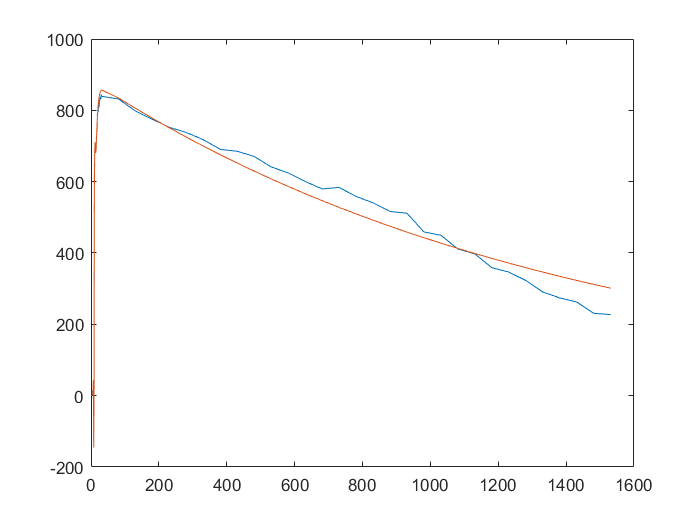


yDataSim(:,1) = decModel(x, tData);
xFit(1,:) = x;

xFitEst = xFit;
fovAve = yData;
fovAveSim = yDataSim;

figure;
plot(tData, [fovAve fovAveSim]);


clearvars minProblem opts problem ms x tElapsed yDataSim xFit allpts

% Add the fitted results to the parameter list (from the function
% script).
clearvars par_val_fit
j=0;
for i = 1:par_set_size
    if par_set(i, 2) == 0
        j = j+1;
        par_val_fit(i,1) = xFitEst(1, j);
    else
        par_val_fit(i,1) = par_set(i, 1);
    end
end
clearvars j i
par_cont = [par_cont, par_val_fit];
clearvars par_val_fit

## Now fit the image pixel by pixel 

x0 = []; x0 = xFitEst';

fitOpt=optimoptions(@lsqcurvefit,...
    'Diagnostics','off');

tiff_stack_sim = [];tiff_stack_par = [];
tiff_stack_sse = []; tiff_stack_residual = [];
sse = []; residual = []; x=[];

tic;
for i = 1:size(tiff_stack, 1)
    for j = 1:size(tiff_stack, 1)
        problem = createOptimProblem('lsqcurvefit','objective',decModel,...
            'x0',x0,...
            'lb',xLow,'ub',xHigh,'xdata',tData,...
            'ydata',...
            reshape (tiff_stack(i, j, :), [size(tData, 1), 1]), ...
            'options', fitOpt);
        
        ms = MultiStart( 'UseParallel', 1, 'Display', 'off');
        [x,sse,residual] = run(ms,problem,5);
        
        tiff_stack_sim(i, j, :) = decModel(x,tData);
        tiff_stack_par(i,j,:) = x;
        tiff_stack_sse(i, j, :) = sse;
        tiff_stack_residual(i, j, :) = residual;
    end
    fprintf('row %d is fnished \n', i)
end

row 1 is fnished 
row 2 is fnished 
row 3 is fnished 
row 4 is fnished 
row 5 is fnished 
row 6 is fnished 
row 7 is fnished 
row 8 is fnished 
row 9 is fnished 
row 10 is fnished 
row 11 is fnished 
row 12 is fnished 
row 13 is fnished 
row 14 is fnished 
row 15 is fnished 
row 16 is fnished 
row 17 is fnished 
row 18 is fnished 
row 19 is fnished 
row 20 is fnished 
row 21 is fnished 
row 22 is fnished 
row 23 is fnished 
row 24 is fnished 
row 25 is fnished 
row 26 is fnished 
row 27 is fnished 
row 28 is fnished 
row 29 is fnished 
row 30 is fnished 
row 31 is fnished 
row 32 is fnished 
row 33 is fnished 
row 34 is fnished 
row 35 is fnished 
row 36 is fnished 
row 37 is fnished 
row 38 is fnished 
row 39 is fnished 
row 40 is fnished 
row 41 is fnished 
row 42 is fnished 
row 43 is fnished 
row 44 is fnished 
row 45 is fnished 
row 46 is fnished 
row 47 is fnished 
row 48 is fnished 
row 49 is fnished 
row 50 is fnished 
row 51 is fnished 
row 52 is fnished 
row 53 is fnished 
ro

tElapsed=toc;
timeElapsed = datestr(datenum(0,0,0,0,0,tElapsed), 'dd HH:MM:SS');
disp(datestr(datenum(0,0,0,0,0,tElapsed), 'dd HH:MM:SS'))

00 01:20:56



clear('i', 'j', 'ans', 'exitflag', 'fitOpt', 'lambda', 'output', 'x',...
    'xHigh', 'xLow', 'decModel', 'tElapsed', 'jacobian', 'residual',...
    'sh_lifetime_max', 'sse', 'x0', "allpts", "estOff", "timeElapsed", ...
    "estBas", "estTau", "estT0", "ms", "problem", "pts", "ptsGen", ...
    "rpts", "tpoints", "tiff_stack_output", "tiff_stack_jacobian", "tiff_stack_lambda", ...
    "tiff_stack_exitflag")

## Save the Simulated Image and Parameter Maps

%% Saving images 
saveastiff(single(tiff_stack_par),...
    'tiff_stack_par.tiff')

The file was saved successfully. Elapsed time : 0.054 s.


ans = 0


saveastiff(single(tiff_stack_sim),...
    'tiff_stack_sim.tiff')

The file was saved successfully. Elapsed time : 0.155 s.


ans = 0